# 
$${\mathrm{Bridge}\;\mathrm{of}\;\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$$


#### By Ari Porad and Jacob Smilg

#### For Quantitative Engineering Analysis 2, April 6th 2021

## Video

A video of our Neato using the code below to successfully traverse the $\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$ is available on YouTube: [https://youtu.be/6AWX_qQ3ueE](https://youtu.be/6AWX_qQ3ueE)

## Code

Our code for this project, including this live script, can be found on GitHub: [https://github.com/ariporad/QEA/tree/main/Robo/hw3](https://github.com/ariporad/QEA/tree/main/Robo/hw3)

## The Challenge

Program the simulated neato robot to autonomously cross the $\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$, as defined by the curve:


$$$r(u)=\left[0.3960\cos(2.65\left(u+1.4\right))\hat{i}-0.99\sin(u+1.4)\hat{j}\right]  \left(u\in{}\left[0,3.2\right]\right)$$$


## Robot Setup

Before we can graph the robot's behavior, we need to define some physical parameters:

% alpha is a linear scalar with time, and controls the speed of the robot
% It's been approximately calibrated to keep the robot's maximum speed
% below the limit of 2 m/s
alpha = 1/5;

% d is the wheelbase of the robot
d = 0.235; % m

% The range of u is specified by the definition of the Bridge of Doom (dun
% dun dun)
U_RANGE = [0 3.2];

% We also convert the range of u into a range of t (u and t are linearly
% correlated) for convinence
T_RANGE = U_RANGE ./ alpha;

% N defines the number of points that will be used for calculating graphs.
% Higher Ns result in higher resolution graphs, but the difference is
% fairly minor.
N = 100;

% Define ranges of ts and us to use for graphs
us = linspace(U_RANGE(1), U_RANGE(2), N)';
ts = us ./ alpha;

% This loads the above equations again from the cannonical equations.m
% file, which we use to ensure that this live script and the code we use to
% drive the neato in the simulator have exactly the same equations, in line
% with the programming principle of DRY (Don't Repeat Yourself)
%
% We've commented this out for our final submission so you can run this
% script by itself without it crashing. See the Methodology section below.

% equations

## Methodology

We begin by setting up the symbolic variables we'll use to process the $\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$:

*All code in this section should be in a file called *`equations.m`*, which is referenced by both this live script and the program that actually drives the robot across the *$\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$*.  We use this pattern to ensure that both scripts use exactly the same equations, in line with the programming principle of DRY (Don't Repeat Yourself).*

% First we must define the symbolic variables we will being using:
syms t omega v_l v_r

% Assumptions help MATLAB not go insane
assume(t, {'real', 'positive'})
assume(omega, 'real')
assume(v_l, 'real')
assume(v_r, 'real')

% This isn't actually a symbolic variable, but we'll set it up anyways
% This allows us to modulate the speed of the robot relative to time by
% adjusting alpha
u = t .* alpha;

% Define the curve of the Bridge of Doom (dun dun dun)
ri=4 * (0.3960 * cos(2.65 * (u + 1.4)));
rj=4 * (-0.99 * sin(u + 1.4));
rk=0*u;
r=[ri,rj,rk]

$$r = \left(\begin{array}{ccc} \frac{198\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{125} & -\frac{99\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$


% Calculate the robot's velocity (rate of change of position) and linear
% speed (magnitude of velocity)
v=diff(r,t)

$$v = \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{6250} & -\frac{99\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{125} & 0 \end{array}\right)$$

speed = norm(v);

% Calculate the unit tangent and unit normal vectors
T_hat=simplify(v./norm(v))

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}} \end{array}$$

dT_hat=simplify(diff(T_hat,t));
N_hat=simplify(dT_hat/norm(dT_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(96725\,\sigma_{6}+140450\,\sigma_{5}+43725\,\sigma_{4}\right)}{\sigma_{1}} & \frac{112360\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)+205057\,\sigma_{3}+92697\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=53\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,t}{50}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,t}{50}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,t}{100}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,t}{100}+\frac{91}{100}\right) \end{array}$$


% Calculate the rotational velocity and speed
omega = simplify(cross(T_hat, dT_hat))

$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)}{4\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}} \end{array}\right)$$

rotation_speed = omega(3);

% Calculate the wheel velocities
v_l = simplify(speed - (rotation_speed * (d / 2)))

$$v\_l = \frac{47\,\left(9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)\right)}{1600\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}}+\frac{99\,\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}}}{6250}$$

v_r = simplify(speed + (rotation_speed * (d / 2)))

$$v\_r = \frac{99\,\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}}}{6250}-\frac{47\,\left(9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)\right)}{1600\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}}$$

## Encoders and Odometry

We load in the saved data from when we ran our code in the simulator, to plot the measured values side-by-side with the calculated ones here.

% We also load our saved encoder data from when we ran our code in the
% simulator
load("encoder_data.mat");

%% The stored encoder data gives us total time and distance, but we also
%% need the relative changes in each sample--so we calculate that here:
enc_dt = diff(enc_t);
enc_dl = diff(enc_l) ./ enc_dt;
enc_dr = diff(enc_r) ./ enc_dt;

%% We also need to derive the wheel, linear, and angular velocities from the
%% measured encoder values.

% Define our symbolic variables
syms vl vr vlin vrot;
assume(vl, 'real');
assume(vr, 'real');
assume(vlin, 'real');
assume(vrot, 'real');

% Define our equations
vl_eqn = vl == vlin - (vrot .* (d ./ 2));
vr_eqn = vr == vlin + (vrot .* (d ./ 2));

% Have MATLAB solve them
[vrot, vlin] = solve([vl_eqn, vr_eqn], [vrot, vlin]);

% Substitute in our data and calculate the answers
vl = enc_dl;
vr = enc_dr;
vrots = double(subs(vrot));
vlins = double(subs(vlin));

%% Finally, we need to calculate the actual path that the robot took from these
%% encoder values

% Define our variables
enc_thetas = zeros(length(enc_t), 1);
enc_rxs = zeros(length(enc_t), 1);
enc_rys = zeros(length(enc_t), 1);

% We need to calculate our initial values differently, because encoders--by
% definition--cannot tell you your starting position. For that, we use our
% calculated path. That's OK because the first command of the neato's
% actual program is to use the magic of the simulator to move the neato to
% the starting position perscribed by the calculated solution.
that_0 = double(subs(T_hat, T_RANGE(1)));
enc_thetas(1) = atan(that_0(2)/that_0(1));
enc_rxs(1) = calculated_path(1, 1);
enc_rys(1) = calculated_path(1, 2);

% Then iteratively calculate each subsequent heading and position
for i=1:length(enc_dt)
    enc_thetas(i + 1) = enc_thetas(i) + (vrots(i) * enc_dt(i));
    enc_rxs(i + 1) = enc_rxs(i) + (vlins(i) * cos(enc_thetas(i + 1)) * enc_dt(i));
    enc_rys(i + 1) = enc_rys(i) + (vlins(i) * sin(enc_thetas(i + 1)) * enc_dt(i));
end

% Finally, calculate the Thats and Nhats from the headings
% We could technically optimize this step since we already do this math
% inside the loop, but Keep-It-Simple-Stupid/"premature optimization is the
% root of all evil"/etc.
enc_Thats = [cos(enc_thetas), sin(enc_thetas)];
enc_Nhats = [-cos(enc_thetas), -sin(enc_thetas)];

## Neato Path Across the $\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$ (Exercise 21.1)

$\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$* with the Neato on it*

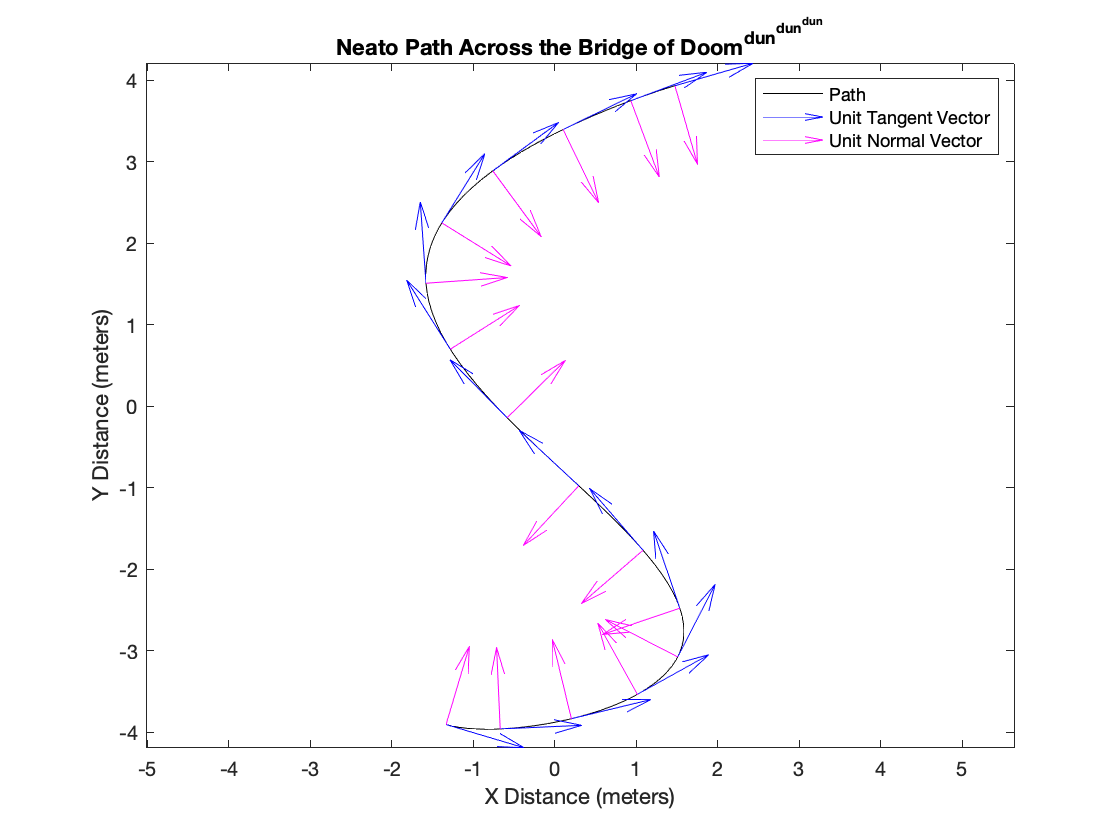

figure(1); clf;

% Calculate and plot the Neato's path
calculated_path = double(subs(r, t, ts));
plot(calculated_path(:, 1), calculated_path(:, 2), 'k-'); axis equal; hold on;

% Calculate and plot unit tangent vectors at various points along the path

% First, pick the points at which to draw the unit tangent vectors
ts_for_arrows = linspace(T_RANGE(1), T_RANGE(2), N / 6)';
start_points_for_calc_arrows = double(subs(r, t, ts_for_arrows));

% Then, calculate vector lengths
calc_that_end_points = double(subs(T_hat, t, ts_for_arrows));
calc_nhat_end_points = double(subs(N_hat, t, ts_for_arrows));

% Finally, plot the vectors
quiver( ...
    start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), ...
    calc_that_end_points(:, 1), calc_that_end_points(:, 2), "off", 'filled', 'b');
quiver( ...
    start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), ...
    calc_nhat_end_points(:, 1), calc_nhat_end_points(:, 2), "off", "filled", 'm');

% Don't forget to label your graphs!
legend("Path", "Unit Tangent Vector", "Unit Normal Vector")
xlabel("X Distance (meters)");
ylabel("Y Distance (meters)");
title("Neato Path Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Neato Speed Across the $\textrm{Bridge}\;\textrm{of}\;{\textrm{Doom}}^{{\textrm{dun}}^{{\textrm{dun}}^{\textrm{dun}} } }$ (Exercise 21.2)

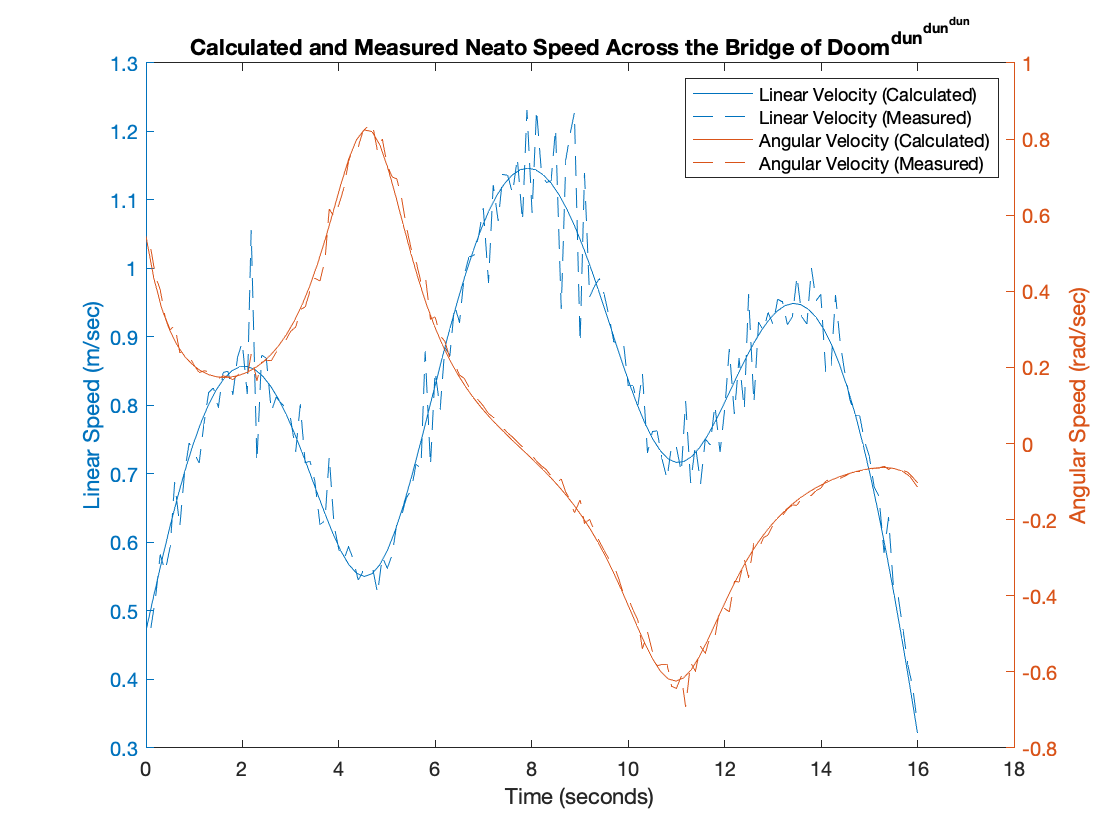

% Calculate the linear and rotational velocities
speeds = double(subs(speed, t, ts));
rot_speeds = double(subs(rotation_speed, t, ts));

figure(2); clf;

% Plot the calculated and measured linear velocities
yyaxis left;
plot(ts, speeds, '-'); hold on;
plot(enc_t(2:end), vlins, '--'); hold off;
ylabel("Linear Speed (m/sec)");

% Plot the calculated and measured angular velocities
yyaxis right;
plot(ts, rot_speeds, '-'); hold on;
plot(enc_t(2:end), vrots, '--'); hold off;

% Don't forget to label your graphs!
xlabel("Time (seconds)");
ylabel("Angular Speed (rad/sec)");
title("Calculated and Measured Neato Speed Across the Bridge of Doom^{dun^{dun^{dun}}}");
legend( ...

    "Linear Velocity (Calculated)", "Linear Velocity (Measured)", ...
    "Angular Velocity (Calculated)", "Angular Velocity (Measured)")

## Neato Wheel Velocities Across the $\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$ (Exercise 21.4)

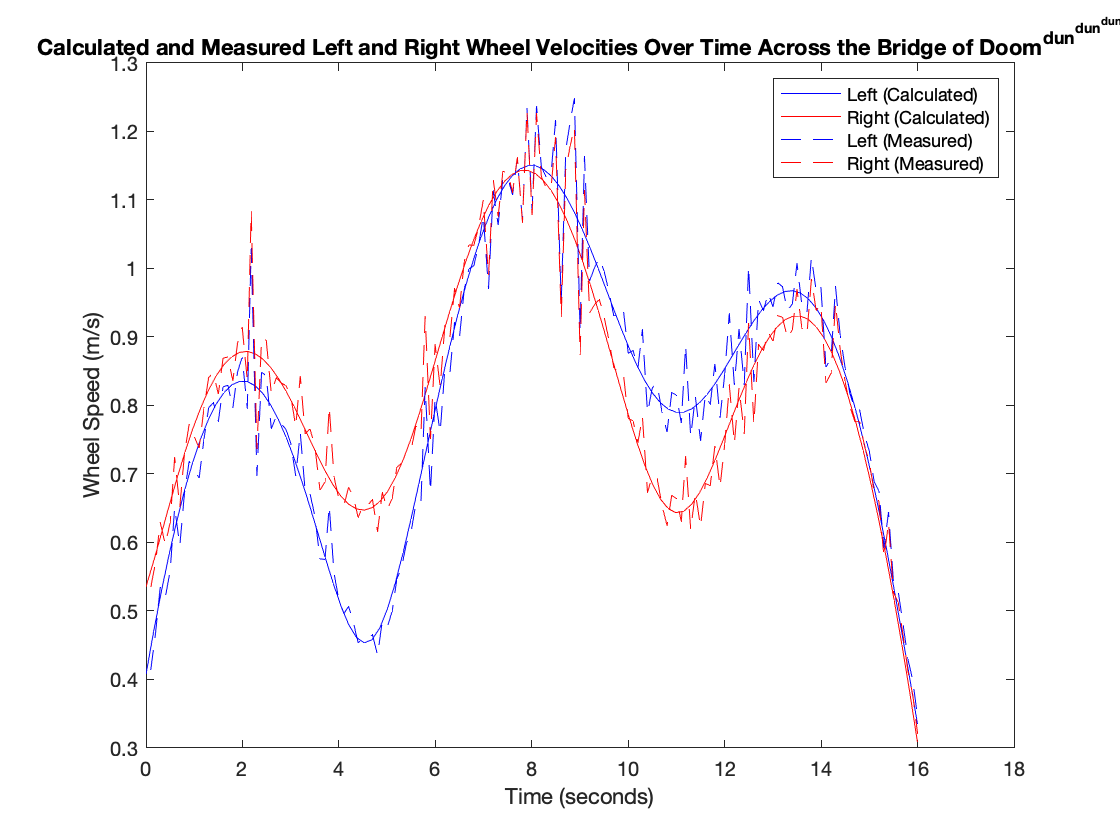

% Calculate the left and right wheel velocities
v_ls = double(subs(v_l, t, ts));
v_rs = double(subs(v_r, t, ts));

% Plot them
figure(3); clf;
plot(ts, v_ls, 'b-'); hold on;
plot(ts, v_rs, 'r-');
plot(enc_t(2:end), enc_dl, 'b--');
plot(enc_t(2:end), enc_dr, 'r--');

% Don't forget to label your graphs!
title("Calculated and Measured Left and Right Wheel Velocities Over Time Across the Bridge of Doom^{dun^{dun^{dun}}}")
xlabel("Time (seconds)");
ylabel("Wheel Speed (m/s)");
legend("Left (Calculated)", "Right (Calculated)", "Left (Measured)", "Right (Measured)");

## Calculated and Measured Neato Wheel Velocities Across the $\textrm{Bridge}\;\textrm{of}\;{\textrm{Doom}}^{{\textrm{dun}}^{{\textrm{dun}}^{\textrm{dun}} } }$ (Exercise 21.5)

Now that we've done our analysis, we can finally plot the calculated path against the plot our Neato actually took, along with the relevant unit tangent vectors.

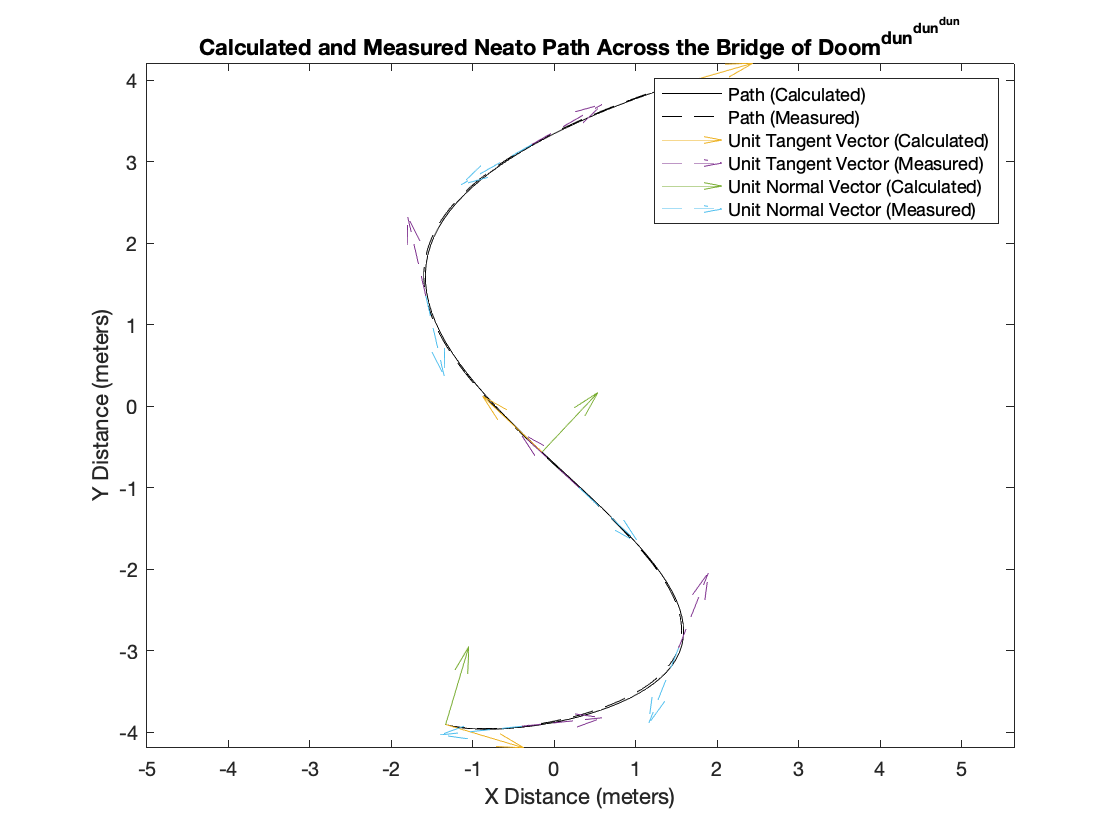

figure(4); clf;

% Plot the paths themselves
plot(calculated_path(:, 1), calculated_path(:, 2), 'k-'); axis equal; hold on;
plot(enc_rxs, enc_rys, 'k--'); 

%% Plot the unit tangent vectors

% This defines how many unit tangent vectors to plot by ploting one every
% this many samples. It will offset the measured and calculated unit
% tangent vectors so they're both visible.
vector_spacing = 30;

% Calculate the predicted values for unit tangent vectors
ts_for_arrows = linspace(T_RANGE(1), T_RANGE(2), N / vector_spacing)';
start_points_for_calc_arrows = double(subs(r, t, ts_for_arrows));
calc_that_end_points = double(subs(T_hat, t, ts_for_arrows));
calc_nhat_end_points = double(subs(N_hat, t, ts_for_arrows));

% Plot the unit tangent vectors
quiver( ...
    start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), ...
    calc_that_end_points(:, 1), calc_that_end_points(:, 2), "off", 'filled', '-');
quiver( ...
    enc_rxs(round(vector_spacing / 2):vector_spacing:end), ...
    enc_rys(round(vector_spacing / 2):vector_spacing:end), ...
    enc_Thats(round(vector_spacing / 2):vector_spacing:end, 1), ...
    enc_Thats(round(vector_spacing / 2):vector_spacing:end, 2), "off", 'filled', '--');

% Plot the unit normal vectors
quiver( ...
    start_points_for_calc_arrows(:, 1), ...
    start_points_for_calc_arrows(:, 2), ...
    calc_nhat_end_points(:, 1), ...
    calc_nhat_end_points(:, 2), "off", "filled", '-');
quiver( ...
    enc_rxs(round(vector_spacing / 2):vector_spacing:end), ...
    enc_rys(round(vector_spacing / 2):vector_spacing:end), ...
    enc_Nhats(round(vector_spacing / 2):vector_spacing:end, 1), ...
    enc_Nhats(round(vector_spacing / 2):vector_spacing:end, 2), "off", "filled", '--');

% Don't forget to label your graphs!
legend( ...
    "Path (Calculated)", "Path (Measured)", ...
    "Unit Tangent Vector (Calculated)", "Unit Tangent Vector (Measured)", ...
    "Unit Normal Vector (Calculated)", "Unit Normal Vector (Measured)")
xlabel("X Distance (meters)");
ylabel("Y Distance (meters)"); 
title("Calculated and Measured Neato Path Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Robot Code for Driving Across the $\mathrm{Bridge}\;\mathrm{of}\;{\mathrm{Doom}}^{{\mathrm{dun}}^{{\mathrm{dun}}^{\mathrm{dun}} } }$ (Exercise 21.4)

*This code should be in a file called *`drive_bod.m`*, and invoked from within the simulator. We've included it here for convinence*

function drive_bod()
    %% Configuration
    % alpha is a linear scalar with time, and controls the speed of the robot
    % It's been approximately calibrated to keep the robot's maximum speed
    % below the limit of 2 m/s
    alpha = 1/5;

    % d is the wheelbase of the robot
    d = 0.235; % m

    % The range of u is specified by the definition of the Bridge of Doom (dun
    % dun dun)
    U_RANGE = [0 3.2];

    % We also convert the range of u into a range of t (u and t are linearly
    % correlated) for convinence
    T_RANGE = U_RANGE ./ alpha;

    % This loads the equations from the cannonical equations.m file, which we
    % use to ensure that this script and the main live script have exactly the
    % same equations, in line with the programming principle of DRY (Don't
    % Repeat Yourself).
    equations;

    % This is the format of the messages we send to the Neato. By packing it
    % into a vector here and converting that from a symbolic value into a
    % matlab function, it becomes much much faster to send commands to the
    % Neato, which increases accuracy.
    msgData = [v_l, v_r];

    % generateMessageData(t) now returns a vector with the right v_l and v_r,
    % without using the Symbolic Toolbox
    generateMessageData = matlabFunction(msgData);

    %% Connect to the Neato 
    disp("Connecting to Neato...")
    pub = rospublisher('raw_vel');

    %% Setup the Neato
    disp("Stopping Neato...")

    % stop the robot if it's going right now
    stopMsg = rosmessage(pub);
    stopMsg.Data = [0 0];
    send(pub, stopMsg);

    disp("Resetting Neato...")

    bridgeStart = double(subs(r,t,0));
    startingThat = double(subs(T_hat,t,0));
    placeNeato(bridgeStart(1),  bridgeStart(2), startingThat(1), startingThat(2));

    % HACK: Wait a bit for robot to fall onto the bridge
    pause(2);

    %% Drive
    disp("Starting to Drive...")

    % Keep track of when we started so we can calculate t 
    rostic;

    while 1 % We'll break out of the loop manually
        % Get the current time
        cur_t = rostoc;

        % If we've hit the end, stop the robot and exit the loop
        if cur_t >= T_RANGE(2)
            stopMsg = rosmessage(pub);
            stopMsg.Data = [0 0];
            send(pub, stopMsg);
            break
        end

        % Otherwise, calculate the speed the Neato should be at and tell it to
        % go at that speed
        speedMsg = rosmessage(pub);
        speedMsg.Data = generateMessageData(cur_t);
        send(pub, speedMsg);
    end

    disp("Done!")
end